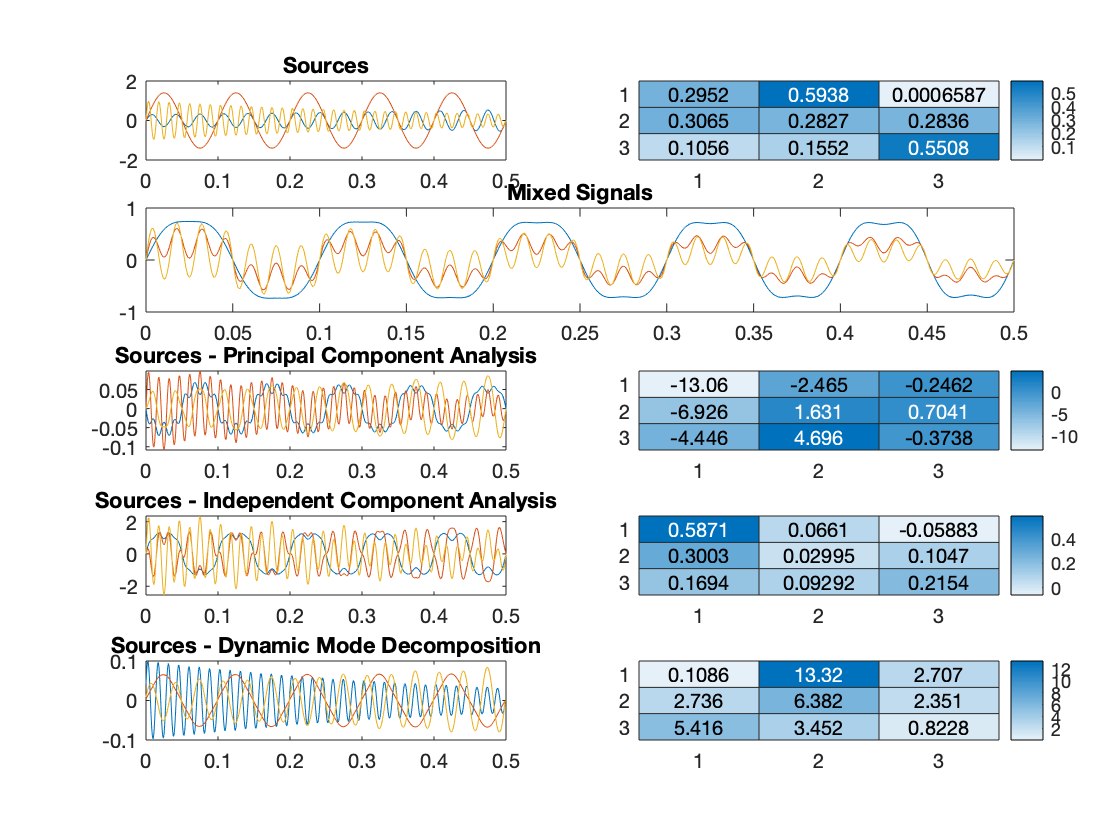

t = 0:0.001:0.5;
N = 3;
S = zeros(N, length(t));

% Decaying gamma
S(3,:) = 1*sin(2*pi*70*t).*exp(-2.3*t);
% Growing Beta
S(1,:) = 0.3*sin(2*pi*30*t).*exp(1.2*t);
% Constant Alpha
S(2,:) = 1.4*sin(2*pi*10*t);
shift = 0.1;
sig = 2*exp(-20*(t-shift));
sig(t<shift) = 0;
if N > 3
    % Add Decay
S(4,:) = sig;
end
if N > 4
    % Add gamma modulated Decay
S(5,:) = sig.*S(3,:);
end

grow = 5; gcol = 2;
figure
subplot(grow,gcol,1)
plot(t, S)
title('Sources')

% Experiment with mixing
% mixing = magic(N);
% mixing = eye(N);
mixing = rand(N);
subplot(grow,gcol,2)
heatmap(mixing);

X = mixing*S;

subplot(grow,gcol,[3,4])
plot(t, X)
title('Mixed Signals')
[Upca, Spca, Vpca] = svd(X, "econ");

subplot(grow,gcol,5)
plot(t, Vpca)
title('Sources - Principal Component Analysis')

subplot(grow,gcol,6)
heatmap(Upca*Spca);

% Play with the ICA Nonlinearities and approaches
[icasig, A, W] = fastica(X,'numOfIC', N, 'initGuess', mixing/20, 'verbose', 'off', 'displayMode', 'off', 'approach', "defl", 'g', "pow3");
% Adjust signs
neg = mean(A,1) < 0;
icasig(neg,:) = -icasig(neg,:);
A(:,neg) = -A(:,neg);

subplot(grow, gcol, 7)
plot(t, icasig)
title('Sources - Independent Component Analysis')

subplot(grow, gcol, 8)
heatmap(A);

[phi, spatial] = DMD(X(:,1:end-1)', X(:,2:end)', N);
subplot(grow, gcol, 9)
% Adjust signs
neg = mean(spatial,1) < 0;
phi(neg,:) = -phi(neg,:);
spatial(:,neg) = -spatial(:,neg);

plot(t(1:end-1), phi)
title('Sources - Dynamic Mode Decomposition')

subplot(grow, gcol, 10)
heatmap(abs(spatial));

## Some observations

FastICA is fairly sensitive to non-stationarity & different parameters, but good at picking out artifacts

PCA is poor for stationary signals that are the same magnitude

Dynamic mode decomposition is sensitive to non-stationarity, and sources sometimes move into the complex plane